## **Normal**

For each distribution, anwser the following questions:

- Is the RV discrete or continuous? **Continuous**

- What is the domain of the RV's PDF or PMF ? **Real numbers**

- Describe the parameters of the distribution: how many are they? What values can they take?  **Standard deviation and mean**

- Give one example of real world phenomenon or data that could be modelled using the distribution. **Central limit theory**

and complete the following tasks:

- Plot the (theoretical) PDF (for contiuous RVs) or PMF (for discrete RVs) and the mean

- Draw a sample of $S=1000$ random outcomes.

- Plot the empirical PDF or PMF of these samples on the same plot created in task 1.

- Plot the (theoretical) CDF

- Plot the empirical CDF of the samples generated in task 2 on the same plot created in task 4.

- Use a Q-Q plot to show the similarity between empirical and theoretical quantiles.

pd = makedist('Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 0
    sigma = 1


outcomes = -4:0.01:4;

outcomes =    -4.0000   -3.9900   -3.9800   -3.9700   -3.9600   -3.9500   -3.9400   -3.9300   -3.9200   -3.9100   -3.9000   -3.8900   -3.8800   -3.8700   -3.8600   -3.8500   -3.8400   -3.8300   -3.8200   -3.8100   -3.8000   -3.7900   -3.7800   -3.7700   -3.7600   -3.7500   -3.7400   -3.7300   -3.7200   -3.7100   -3.7000   -3.6900   -3.6800   -3.6700   -3.6600   -3.6500   -3.6400   -3.6300   -3.6200   -3.6100   -3.6000   -3.5900   -3.5800   -3.5700   -3.5600   -3.5500   -3.5400   -3.5300   -3.5200   -3.5100


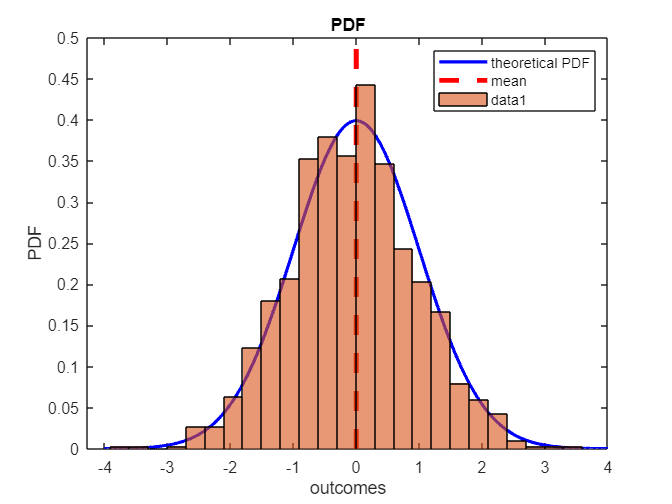

th_pdf = pdf(pd, outcomes);
% Create small and large samples
sample = random(pd,1,1000);

% Generate plot data
clf; % clear the figure
plot(outcomes, th_pdf, 'b', 'LineWidth', 2)
hold on
th_mean = mean(pd); % Let's plot the distribution mean
line([th_mean,th_mean],[0,0.5], 'LineStyle', '--', 'Linewidth', 3,'Color','red');
legend('theoretical PDF', 'mean', 'Location','northeast')
title('PDF') % title for plot
xlabel('outcomes') % x-axis label
ylabel('PDF') % y-axis label

th_epmf = histogram(sample, 'normalization', 'pdf'); % correctly normalised

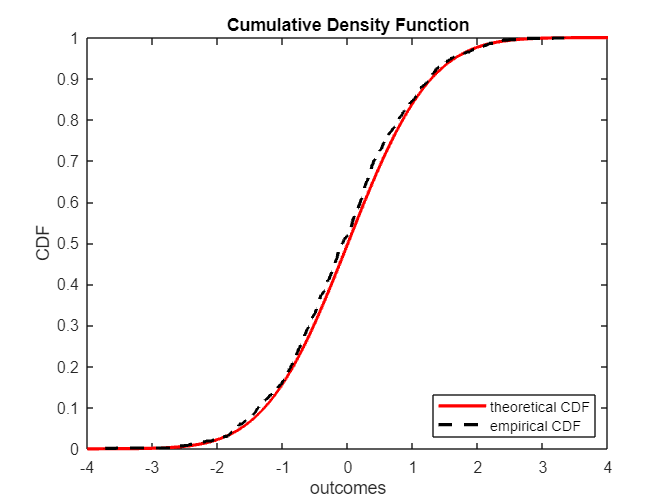

% Create cumulative density function
th_cdf = cdf(pd, outcomes);

clf % clear the plot
stairs(outcomes, th_cdf, '-r', 'LineWidth', 2)
hold on
legend('theoretical CDF', 'Location','southeast')
title('Cumulative Density Function') % title for plot
xlabel('outcomes') % x-axis label
ylabel('CDF') % y-axis label

[x_ecdf, y_ecdf] = ecdf(sample);
stairs(y_ecdf, x_ecdf, '--k', 'LineWidth',2)
legend('theoretical CDF','empirical CDF')

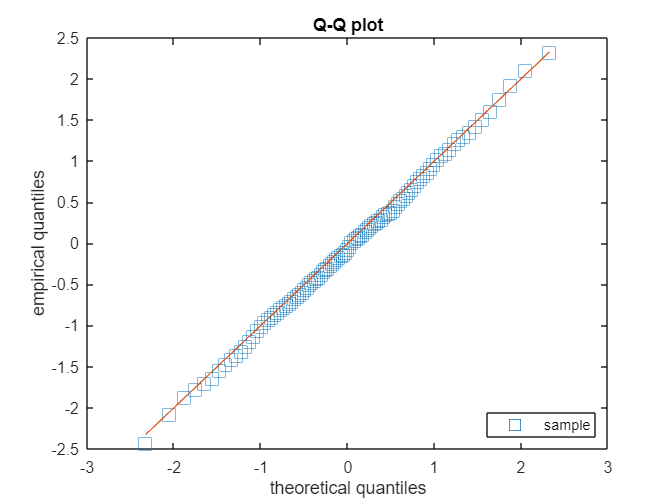

% evaluate at more points within 0 and 1
clf
pp = 0: 0.01: 1;
theor_q = icdf(pd, pp);
empir_q = quantile(sample, pp);
plot(theor_q, empir_q, 's', 'MarkerSize', 10)
hold on
plot(theor_q, theor_q, '-','HandleVisibility','off')
legend('sample', 'Location','southeast')
title('Q-Q plot') % title for plot
xlabel('theoretical quantiles') % x-axis label
ylabel('empirical quantiles') % y-axis label